# Visualisation_profile_D3

2023年3月2日 11:59:59 by liman

% load resisivity, Temperature, model data

% The size of profile meshs are 76 (nx: Horizontal direction) x 60 (nz: vertical direction)

1. load data 

clc;clf;close all;clear;
% load profile data
load("profile_D3.mat");
% smooth resisitivity data
% RHO = smoothdata(rho,2,'gaussian',10);
K = 0.1*ones(6);
RHO_conv2= conv2(rho,K,'same');

2. calculate viscosity

for i =1: nz
    for j=1: nx
        if (RHO_conv2(i,j) <= 0 )
            RHO_conv2(i,j) = NaN;
        end
    end 
end
nu = cal_visco_LabData(nx,nz,Temf,P,C0,RHO_conv2);
% nu = cal_visco_(nx,nz,Temf,RHO_conv2);
NU = smoothdata(nu,'gaussian'); %1300k会有分割
NU_wet = cal_visco_LabData_wet(nx,nz,Temf,P,C0,RHO_conv2);
NU_dry = cal_visco_LabData_dry(nx,nz,Temf,P,RHO_conv2);

plot viscosity (log$\rho \;$) profile

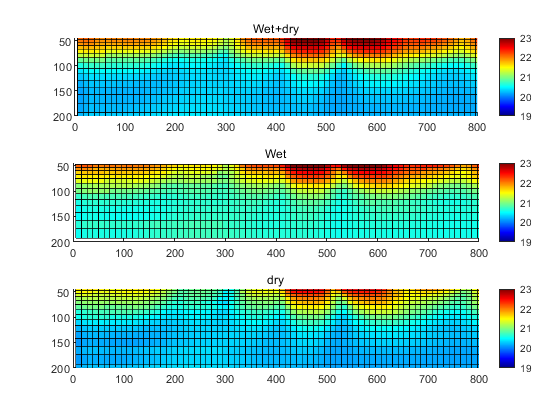

figure( );
tiledlayout(3,1,'TileSpacing','compact');
%Tile1
nexttile
logNU = log10(NU);
surface(dx,dz,logNU);
% shading interp;
axis ij image;
ylim([45 200]);
xlim([0 800]);
colorbar;
colormap(jet)
caxis([19 23]);
title("Wet+dry")
%Tile2
nexttile
logNU_wet = log10(NU_wet);
surface(dx,dz,logNU_wet);
% shading interp;
axis ij image;
ylim([45 200]);
xlim([0 800]);
colorbar;
colormap(jet)
caxis([19 23]);
title("Wet")
%Tile3
nexttile
logNU_dry = log10(NU_dry);
surface(dx,dz,logNU_dry);
% shading interp;
axis ij image;
ylim([45 200]);
xlim([0 800]);
colorbar;
colormap(jet)
caxis([19 23]);
title("dry");